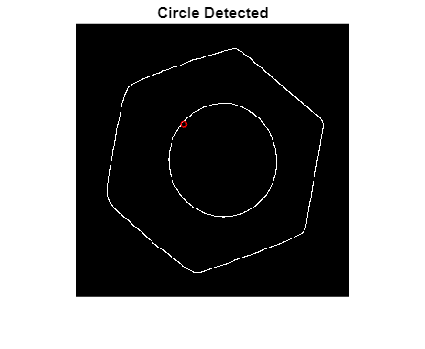

im = imread('HW2.jpg');
image_bw=rgb2gray(im);
img_BW = imbinarize(image_bw); 
img_BW = imcomplement(img_BW); 
edgeImg=edge(img_BW,'canny');

[gx,gy] = imgradientxy(edgeImg);
offset = 300;
accum = zeros(600,600,100);
B = bwboundaries(edgeImg,'holes');
B = B{2}; 

for R = 1:100
    for i=1:size(B,1)
           x=B(i,2);
           y=B(i,1);
            if (gx(x,y)~=0 || gy(x,y)~=0)
                
            xc = round(y - R*gx(x,y)/sqrt(gx(x,y)^2+gy(x,y)^2));
            yc = round(x - R*gy(x,y)/sqrt(gx(x,y)^2+gy(x,y)^2));
            
            accum(xc+offset,yc+offset,R) = accum(xc+offset,yc+offset,R) + 1;
            
            end
    end
end
[~,index] = max(accum(:));
[maxx, maxy, maxr] = ind2sub(size(accum),index);

peak = houghpeaks(accum(:,:,1),1);
xc = peak(1,1)-offset;
yc = peak(1,2)-offset;
R = maxr;
th = 0:pi/50:2*pi;
x = R * cos(th) + xc;
y = R * sin(th) + yc;
figure 
imshow(edgeImg)
hold on
plot(x, y,'r');
title('Circle Detected')
hold off